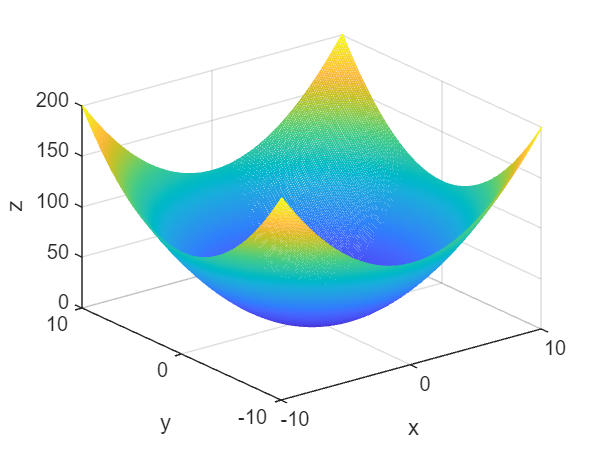

% Define the function
f = @(x, y) x.^2 + y.^2;

% Define the range and step size for x and y
x = -10:0.1:10;
y = -10:0.1:10;

% Create a grid of points in the x-y domain
[X, Y] = meshgrid(x, y);

% Evaluate the function at the grid points to obtain z-values
Z = f(X, Y);

% Plot the 3D graph
figure;
mesh(X, Y, Z);
xlabel('x');
ylabel('y');
zlabel('z');



% Compute the gradients along x and y
[gx, gy] = gradient(Z, x, y);

% Compute the second derivatives along x and y
[gxx, gxy] = gradient(gx, x, y);
[gyx, gyy] = gradient(gy, x, y);


% Set the threshold for identifying bends
threshold = 0.01;

% Find the indices of the points where the second derivatives are close to zero
[bendX, bendY] = find(abs(gxx) < threshold & abs(gyy) < threshold);

% Plot the bends on the 3D graph
figure;
plot3(X(bendX, bendY), Y(bendX, bendY), Z(bendX, bendY), 'ro', 'MarkerSize', 5);

